Km = 0.3249

Km = 0.3249

Ke = 0.3249

Ke = 0.3249

J = 0.0016

J = 0.0016

R = 4.6808

R = 4.6808

L = 1.0411

L = 1.0411

W = tf(Km/J/R, [1 Ke*Km/J/R])

W =
 
    43.38
  ---------
  s + 14.09
 
Continuous-time transfer function.



b = Km/J/R

b = 43.3820

a = Ke*Km/J/R

a = 14.0948

syms w s t
% pereh = 1/Ke-1/Ke*exp(-a*t)
% fplot(pereh,[0,1])
% achx
afc = b/(sqrt(a^2+w^2))

$$afc = \frac{6105474754134719}{140737488355328\,\sqrt{w^{2}+\frac{3494930300964891}{17592186044416}}}$$

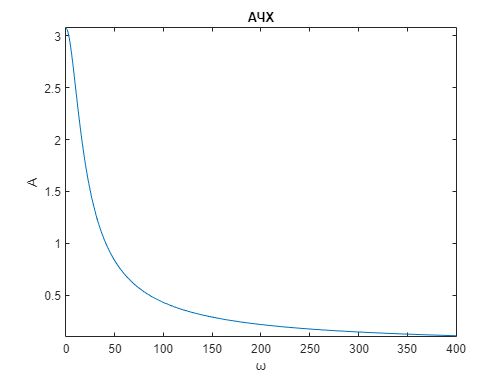

fplot(afc,[0,400])

title("АЧХ")
xlabel("ω")
ylabel("A")


% фчх
pfc= atan(-w/a)

$$pfc = -\mathrm{atan}\left(\frac{281474976710656\,w}{3967337495236741}\right)$$

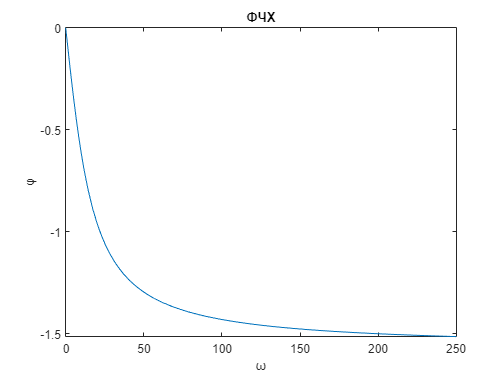

fplot(pfc,[0,250])

title("ФЧХ")
xlabel("ω")
ylabel("φ")

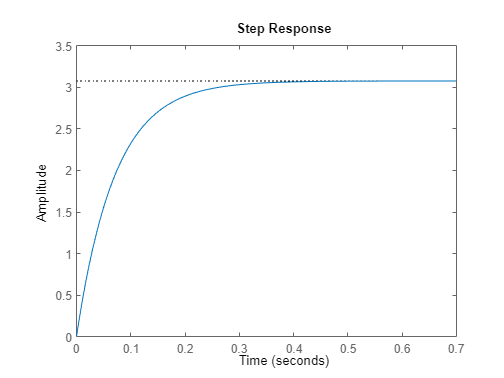

step(W)

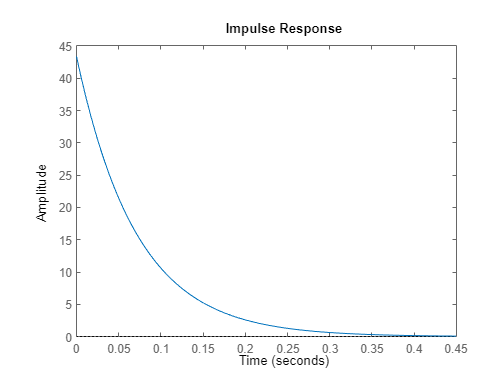

impulse(W)

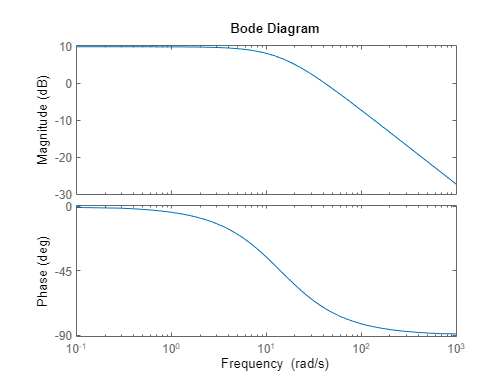

bode(W)